clear

buf_len = 1e5;

az_max = 359.9;
el_max = 70;
r_max = 10e3;

az_min = 0;
el_min = 0;
r_min = 100;

in = [az_max - az_min, el_max - el_min, r_max - r_min] .* rand(buf_len,3) + [az_min, el_min, r_min];

az_in = round(in(:,1),1);
el_in = round(in(:,2),1);
r_in = round(in(:,3),0);

% az_in = 255.39917;
% el_in = 88.901367;
% r_in = 1798;
% buf_len = 1;

% az_in = (0:0.1:az_max)';
% buf_len = length(az_in);
% el_in = 45.0 * ones(buf_len,1);
% r_in = 1000 * ones(buf_len,1);



az_in = round(az_in * 2^14 / 180, 0);
el_in = round(el_in * 2^14 / 180, 0);
r_in = round(r_in, 0);

in_sph = [az_in * 180 / 2^14, el_in  * 180 / 2^14, r_in];
[in_card(:,1), in_card(:,2), in_card(:,3)] = sph2cart(deg2rad(in_sph(:,1)), deg2rad(in_sph(:,2)), in_sph(:,3));

az_out = zeros(buf_len,1);
el_out = zeros(buf_len,1);
r_out = zeros(buf_len,1);

for i=1:buf_len
    [az_out(i), el_out(i), r_out(i)] =...
        ParalaxCalc(az_in(i), el_in(i), r_in(i));
end

out_sph = [180 / 2^14 * double(az_out), 180 / 2^14 * double(el_out), double(r_out)];

[az_out_ref, el_out_ref, r_out_ref] = ParalaxCalcRef(az_in, el_in, r_in);

out_ref_sph = [180 / 2^14 * double(az_out_ref), 180 / 2^14 * double(el_out_ref), double(r_out_ref)];


delta_ref = abs(out_sph - out_ref_sph);
delta_ref((delta_ref(:,1) > 180),1) = 360 - delta_ref((delta_ref(:,1) > 180),1);
[max_delta, ind] = max(delta_ref,[],1);
disp(['delta Az: ', num2str(max_delta(1)), ' in sph: ', num2str(in_sph(ind(1),:))]);

delta Az: 0 in sph: 110.69824      3.5046387           5013


disp(['delta El: ', num2str(max_delta(2)), ' in sph: ', num2str(in_sph(ind(2),:))]);

delta El: 0 in sph: 110.69824      3.5046387           5013


disp(['delta R: ', num2str(max_delta(3)), ' in sph: ', num2str(in_sph(ind(3),:))]);

delta R: 0 in sph: 110.69824      3.5046387           5013


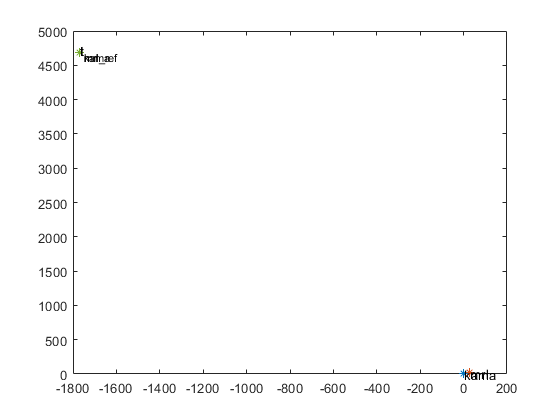



[out_card(:,1), out_card(:,2), out_card(:,3)] = sph2cart(deg2rad(out_sph(:,1)), deg2rad(out_sph(:,2)), out_sph(:,3));
[out_ref_card(:,1),out_ref_card(:,2),out_ref_card(:,3)] = sph2cart(deg2rad(out_ref_sph(:,1)), deg2rad(out_ref_sph(:,2)), out_ref_sph(:,3));


% delta = abs(out - in);
% disp(max(delta(:,1)));
% disp(max(delta(:,2)));
% disp(max(delta(:,3)));

x_base = 29;
y_base = 17;
z_base = 11;

% plot3(in_card(:,1),in_card(:,2),in_card(:,3));
% hold on
% plot3(out_card(:,1),out_card(:,2),out_card(:,3));
% hold on
% plot3(out_card(:,1)-x_base,out_card(:,2) - y_base,out_card(:,3) - z_base);
% hold off

out_card = out_card - [x_base, y_base, z_base];
out_ref_card = out_ref_card - [x_base, y_base, z_base];


in_card = in_card(ind(1),:);
out_card = out_card(ind(1),:);
out_ref_card = out_ref_card(ind(1),:);

plot(0,0, x_base, y_base, in_card(:,1),in_card(:,2), out_ref_card(:,1), out_ref_card(:,2),out_card(:,1),out_card(:,2),...
    'Marker',"*");
text([0, x_base, in_card(:,1), out_ref_card(:,1), out_card(:,1)],...
     [0, y_base, in_card(:,2), out_ref_card(:,2), out_card(:,2)], ...
     ["kama","mrl","t_{kama}", "t_{mrl\_ref}", "t_{mrl}"]);